# Polifase

**Sea un sistema conformado por un filtro digital FIR con transferencia H(z), de orden N=299,**

** 𝜔c =𝜋/M y 𝛥𝜔=0.01𝜋 (suponga una ventana de Kaiser con beta=10) y un bloque de diezmado con un factor de M=3, como el de la Figura. **

                    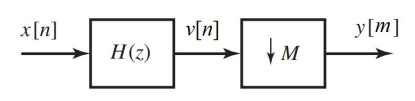

**a) Suponga que el filtro H(z) se puede representar con una realización mediante la forma directa para un periodo de muestreo Ts en la entrada. ¿Cuántas operaciones por unidad de tiempo son requeridas para obtener la señal de salida y(m)? Nota: tome cómo referencia las multiplicaciones necesarias en un intervalo de tiempo Ts para representar la cantidad de operaciones por segundo.**

clc; clear; close all;
pb= @(nm, wc, N)( (wc/pi) .* sinc((wc/pi) .* (nm - N/2)) );
%Orden del filtro de Kaiser.
N= 299;
%
nm = 0:N;
%Ancho de banda de transicion.
Dw = 0.01*pi;
%Beta.
Beta = 10;
%Factor de diesmado.
M = 3;
%Frecuencia de corte.
wc= pi/M;

%filtro deseado. 
hd = pb(nm, wc, N);
%Ventana de Kaiser.
WindK = kaiser(M, Beta)';
%Ventana de Kaiser.
h = conv(hd, WindK);

Para generar diesmado por M = 3 se debe descomponer en tres $P_i$ osea $P_1$ $P_2$ y $P_3$ para ello cada decimacion en forma directa será:

Ts2 = Ts*3

luego por cada $P$ es:

(N+1) + (N+1)+(N+1):

entonces $(N+1) + (N+1)+(N+1) / Ts*3$ = $(N+1)/Ts$ que es lo mismo que antes, pero se puede mejorar aplicando identidades.

**c)**

**Obtenga las componentes polifásicas pk (n) del filtro H(z), con M=3 y grafíquelas en el tiempo. Nota: las componentes polifásicas para un filtro decimador pueden computarse por definición, aunque en matlab también se pueden obtener mediante: p = polyphase(Hdec), donde Hdec = dsp.FIRDecimator(M,h).**

% Hdec = dsp.FIRDecimator(M, h)
% p = polyphase(Hdec)

%Genero mi propia funcion polifase, devuelve una matriz pk.
pk = polifase(M, h)

pk =    -0.0000   -0.0011    0.0011   -0.0011    0.0011   -0.0012    0.0012   -0.0012    0.0013   -0.0013    0.0013   -0.0014    0.0014   -0.0014    0.0015   -0.0015    0.0016   -0.0016    0.0016   -0.0017    0.0018   -0.0018    0.0019   -0.0020    0.0020   -0.0021    0.0022   -0.0023    0.0024   -0.0025    0.0026   -0.0028    0.0029   -0.0031    0.0033   -0.0035    0.0037   -0.0040    0.0044   -0.0048    0.0052   -0.0058    0.0065   -0.0074    0.0086   -0.0103    0.0127   -0.0168    0.0245   -0.0455
   -0.0011    0.0011   -0.0011    0.0011   -0.0012    0.0012   -0.0012    0.0012   -0.0013    0.0013   -0.0013    0.0014   -0.0014    0.0014   -0.0015    0.0015   -0.0016    0.0016   -0.0017    0.0017   -0.0018    0.0018   -0.0019    0.0020   -0.0021    0.0021   -0.0022    0.0023   -0.0024    0.0025   -0.0027    0.0028   -0.0030    0.0032   -0.0034    0.0036   -0.0038    0.0041   -0.0045    0.0049   -0.0054    0.0060   -0.0068    0.0078   -0.0091    0.0110   -0.0138    0.0187   -0.0290    

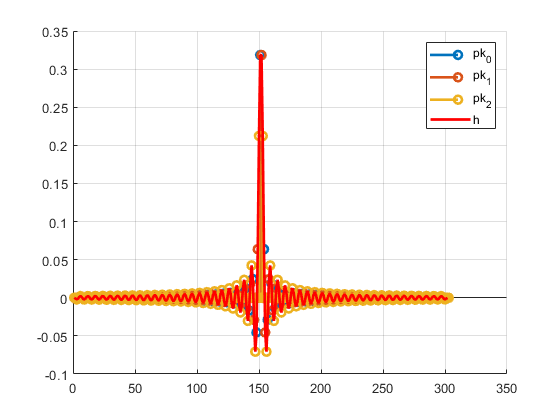


%Hago el sobremuestreo (Expansion)
P = zeros(M, length(h));
for i = 1:M
     P(i, i:M:length(h)+1) = pk(i, :);
 end

%-Ploteo las polifases pero sobremuestreada (expandidas) para compararlas
%con el filtro.
figure()
    hold on;
    for i= 1:M
        stem(1:length(P), P(i, :), 'LineWidth', 2)
    end
    plot(1:length(h), h,  '-r', 'LineWidth', 2)
    legend("pk_0", "pk_1", "pk_2", "h")
    grid on

**d)**

**Para ambos sistemas, Figuras 1 y 2, aplique alguna de las pistas de audio utilizadas en los TPs 1 y 2 cómo entrada x(n) y compare las salidas de ambos sistemas. Sugerencia: si utiliza filter(), en lugar de conv(), considere un largo de la entrada suficiente para evitar que la función recorte muestras de más. Puede además truncar la señal de entrada a 1000 muestras. **

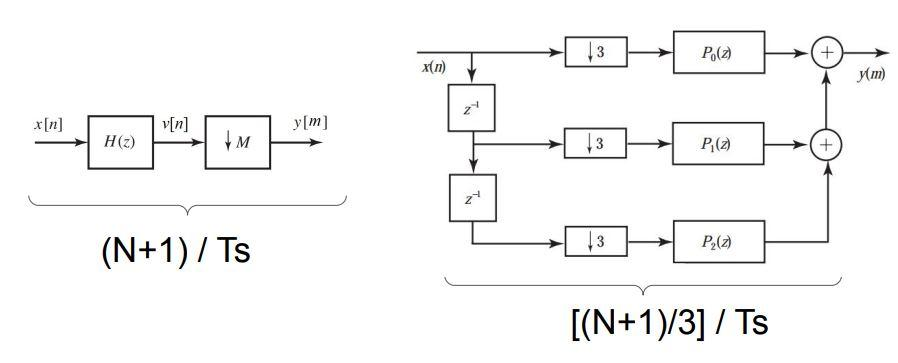

                figura *1.                                                               figura_2.*

%cargamos una pista de audio:
[x1, FS1] = audioread('Pista_01.wav');
x1 = x1(1:1000);  %trunco las muestras hasta 1k
nfft= 2*length(x1);

%Para figura 1:
v = conv(h,x1);
y1 = downsample(v, M);

%Para figura 2:
%pki / i={0, 1, 2...M} . ya lo tengo

%Señal retrasada y decimada:
yk_D = zeros( M, ceil(length(x1')/M + M - 1) );
%Señal retrasada, decimada y pasada por el filtro:
%Tener en cuenta que conv([1...N], [1...N]) = [1...(N+N-1)], probar.
                            %yk_DP = zeros(M, length(yk_D) + length(pk) -1);
length_y_aux = ceil((length(x1)+ (M-1))/M)

length_y_aux = 334

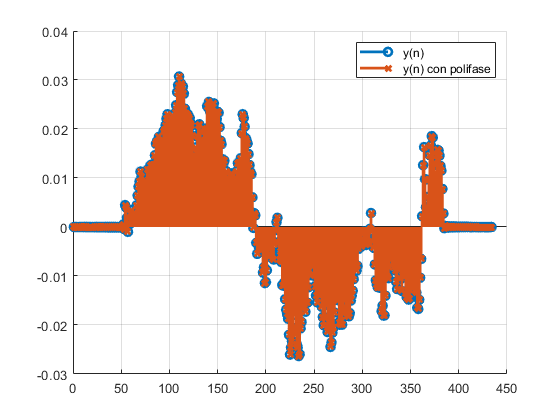

yk_DP = zeros(M, length_y_aux + length(pk) -1);
%Aplico [retraso[z^-1] -> decimacion[\|/ M]-> Poli[pk] ] =h(n)
                            % for i = 1:M
                            %     
                            %     %submuestreo (comprimo)
                            %     y_aux = downsample(x1(i:end), M);
                            %     %Aplico el retardo (colocar los ceros antes de la señal)
                            %     yk_D(i, i: length(y_aux) + (i-1) ) = y_aux;
                            %     %hago la comvolucion a cada señal retrasa y submuestreada.
                            %     yk_DP(i,:) = conv(yk_D(i,:), pk(i,:));
                            % end
for i = 1:M
   %retardo [z^-1]
   y_aux = [zeros(1, i-1), x1'];
   %decimacion[\|/ M]
   y_aux = downsample(y_aux, M);
   %Poli[pk] ] =h(n)
   l_conv = (length(y_aux) + length(pk) -1); %largo de la convolucion
   yk_DP(i,1: l_conv) = conv(y_aux, pk(i,:));
end
%Sumo cada componente
y2 = sum(yk_DP);
Y = fft(y2, nfft);

figure()
    hold on
    stem(1:length(y1), y1, '-o', 'LineWidth', 2)
    stem(1:length(y2), y2, '-x','LineWidth', 2)
    grid on
    legend("y(n)", "y(n) con polifase")

# Actividad 3 D. 

# polifásica con interpolación

**Sea un sistema conformado por un bloque de expansión con un factor de L=3 en cascada con un filtro interpolador con transferencia H(z) (con mismas especificaciones que en el ejercicio anterior), de acuerdo a la Figura:**

                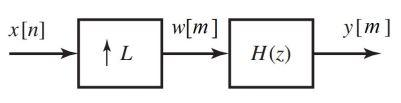

**a) Suponga que la respuesta impulsiva h(n) es un filtro FIR de orden N, implementado mediante la forma directa para un periodo de muestreo Ts en la entrada. ¿Cuántas operaciones por unidad de tiempo son requeridas para obtener la señal de salida y(m)?**

** Nota: tome cómo referencia las multiplicaciones necesarias en un intervalo de tiempo Ts para representar la cantidad de operaciones por segundo.**

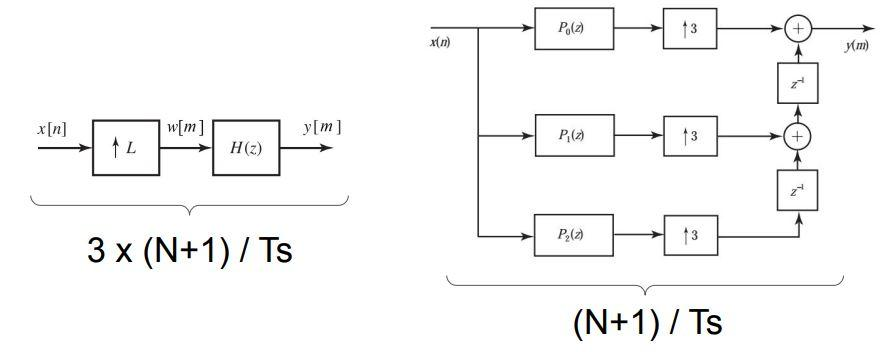

**c)**

** Obtenga las componentes polifásicas pk (n) del filtro H(z), con L=3 y grafíquelas en el tiempo. Nota: las componentes polifásicas para un filtro interpolador pueden computarse por definición, aunque en matlab también se pueden obtener mediante: p=polyphase(Hdec), donde Hint=dsp.FIRInterpolator(L,h).**

%las polifase son las mismas y L = M en este caso, asi que uso tal cual
L = 3;
Hint = dsp.FIRInterpolator(L, h);
pk=polyphase(Hint)

pk =    -0.0000   -0.0011    0.0011   -0.0011    0.0011   -0.0012    0.0012   -0.0012    0.0013   -0.0013    0.0013   -0.0014    0.0014   -0.0014    0.0015   -0.0015    0.0016   -0.0016    0.0016   -0.0017    0.0018   -0.0018    0.0019   -0.0020    0.0020   -0.0021    0.0022   -0.0023    0.0024   -0.0025    0.0026   -0.0028    0.0029   -0.0031    0.0033   -0.0035    0.0037   -0.0040    0.0044   -0.0048    0.0052   -0.0058    0.0065   -0.0074    0.0086   -0.0103    0.0127   -0.0168    0.0245   -0.0455
   -0.0011    0.0011   -0.0011    0.0011   -0.0012    0.0012   -0.0012    0.0012   -0.0013    0.0013   -0.0013    0.0014   -0.0014    0.0014   -0.0015    0.0015   -0.0016    0.0016   -0.0017    0.0017   -0.0018    0.0018   -0.0019    0.0020   -0.0021    0.0021   -0.0022    0.0023   -0.0024    0.0025   -0.0027    0.0028   -0.0030    0.0032   -0.0034    0.0036   -0.0038    0.0041   -0.0045    0.0049   -0.0054    0.0060   -0.0068    0.0078   -0.0091    0.0110   -0.0138    0.0187   -0.0290    


%Hago el sobremuestreo (Expansion)
P = zeros(L, length(h));
for i = 1:L
     P(i, i:M:length(h)+1) = pk(i, :);
 end

%-Ploteo las polifases pero sobremuestreada (expandidas) para compararlas
%con el filtro.
figure()
    hold on;
    for i= 1:M
        stem(1:length(P), P(i, :), 'LineWidth', 2)
    end
    plot(1:length(h), h,  '-r', 'LineWidth', 2)
    legend("pk_0", "pk_1", "pk_2", "h")
    grid on

%Es lo mismo que antes.

**d) **

**Para ambos sistemas, Figuras 1 y 2, aplique alguna de las pistas de audio utilizadas en los TPs 1 y 2 cómo entrada x(n) y compare las salidas de ambos sistemas. Sugerencia: si utiliza filter(), en lugar de conv(), considere un largo de la entrada suficiente para evitar que la función recorte muestras de más.**

%aplicnado el filtro sin polifase
y3 = filter(h, 1, upsample(x1', L));

%Aplicando el filtro con polifase
%pk late.
%[x]-->[P0]
%[x]-->[P1]        }xp
%[x]-->[P2]
xp = zeros(L, length(x1)) % por lo general length(x1) > length(pk)

xp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


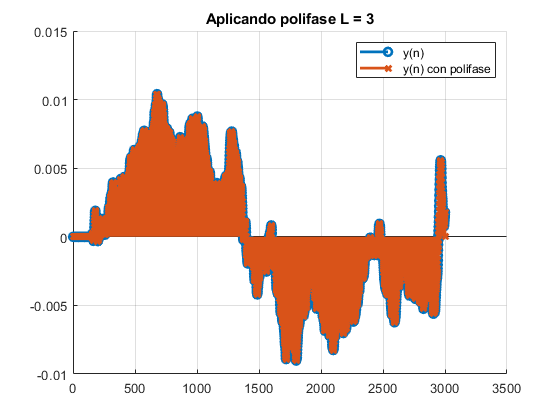

for i= 1:L
    xp(i, 1:length(x1)) = filter(pk(i,:), 1, x1);
end

%Obtengo los pk interpolados de a L=3.
yk = zeros(L, length(x1)*L - 1);
for i = 1:M
    %[xp]-->[Pi(z)] --> [/|\ L]
    yk_aux = upsample(xp(i,:), L);
    %[xp]-->[Pi(z)] --> [/|\ L] --> [z^-1]
    yk_aux = [zeros(1, i-1), yk_aux];
    %Se lo asigno a la matris yk
    yk(i, 1:length(yk_aux)) = yk_aux;
end

%Sumo cada componente
y4 = sum(yk);
Y4 = fft(y3, nfft);

figure()
    hold on
    stem(1:length(y3), y3, '-o', 'LineWidth', 2)
    stem(1:length(y4), y4, '-x','LineWidth', 2)
    grid on
    legend("y(n)", "y(n) con polifase")
    title("Aplicando polifase L = 3")

# Actividad 4 

# IFIR

**Se requiere implementar un filtro pasa bajos con una transición muy estrecha, h(n) con frecuencias límites 𝜔 p =0.05𝜋 y 𝜔 s =0.1𝜋, ripples de paso 𝛿 p=0.01 y supresión 𝛿 s =0.001. **

wp = 0.05*pi;
ws = 0.1*pi;
deltaP = 0.01;
deltaS = 0.001;

**a) Implemente h(n) y grafique su respuesta en frecuencia para verificar si cumple las especificaciones y observe el orden requerido para su cumplimiento. **

**b) Implemente un filtro IFIR de modo tal que el filtro completo HIFIR(z) (cascada del filtro interpolador I(z) y el modelo G(zM), con M=5) cumpla las mismas especificaciones que H(z). Grafique en un mismo esquema la respuesta en frecuencia de G(z), G(zM), I(z) y HIFIR(z). En un esquema separado, grafique |H(𝜔)| y |HIFIR(𝜔)| y compare ambas implementaciones. **

**c) De los resultados observados en el punto anterior, determine el ahorro de coeficientes requeridos para la implementación de IFIR respecto del filtro original (puede expresarlo como porcentaje [%] en relación al filtro original).** 

                

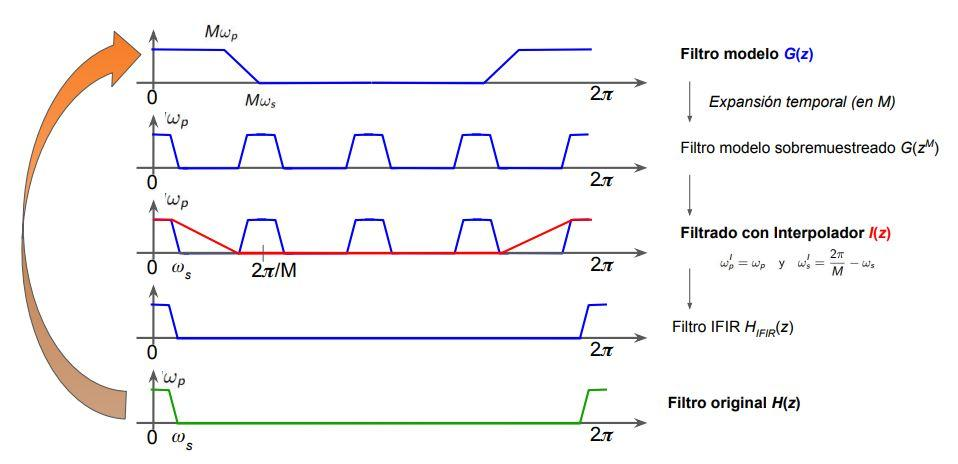

function [pk] = polifase(M, h)
%Genero los polifase a partir de mi h, si un polifase es de menor tamaño
%que el resto entonces se completa automaticamente con un cero.


    pk = zeros(M, ceil( length(h)/M ));%zeros(1, length(h/M));
    % 
    %Polifase: Pk(Z)
    for k = 1:M
        p_aux = h(k:M:end);
        pk( k, 1:length(p_aux) )= p_aux;
    end

end
    
% function [pk] = polifase_Interpolador(M, h)
% %Genero los polifase a partir de mi h, si un polifase es de menor tamaño
% %que el resto entonces se completa automaticamente con un cero.
% 
%     pk = zeros(M, ceil( length(h)/M ));%zeros(1, length(h/M));
%     % 
%     %Polifase: Pk(Z)
%     for k = 1:M
%         p_aux = h(k:M:end);
%         pk( k, 1:length(p_aux) )= p_aux;
%     end
% 
% end
% function [M, Beta] = parametrosKaiser(ripple, Dw)
%     %-% Ventana de Kaiser
%     xx = sym('x');
% 
%     %Obtengo los parametros de Kaiser.
%     A= -20*log10(ripple);
%     M = ceil( (A-8)/(2.285*Dw) + 1);
%     %N= M-1;
%     %nm= 0:N;
%     
%     %Funcion para calcular Beta
%     fBeta = piecewise(xx > 50,       0.1102*(xx-8.7), ...
%             (21<= xx) & (xx <= 50),   0.5842*(xx-21)^0.4 + 0.07886*(xx-21), ...
%                     xx < 21,         0);
%     %Beta.
%     Beta = double(subs(fBeta, xx, A));
% 
% end